# Lecture 2: Invertibility and minimum-phase systems

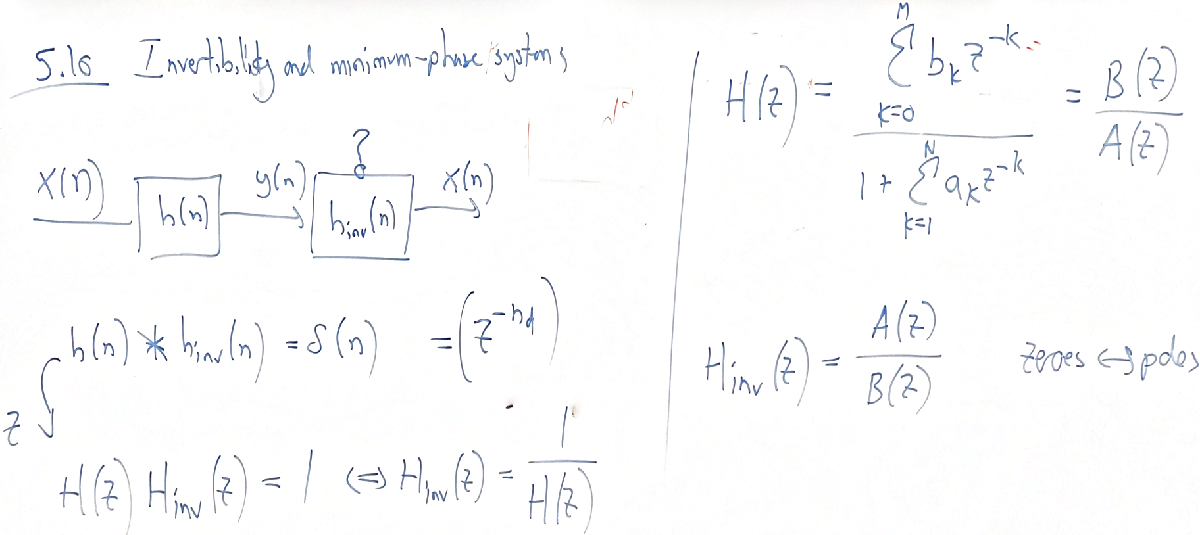

## When is a filter invertible?

For a filter to be invertible, zeros and poles must be inside the unit circle.

A causal and stable LTI system with a causal and stable inverse is known as a *minimum-phase* system 

If poles and zeros are outside the unit circle, we call it maximum-phase.

If some are outside and others inside the unit circle, it is known as mixed-phase. 

### Quiz

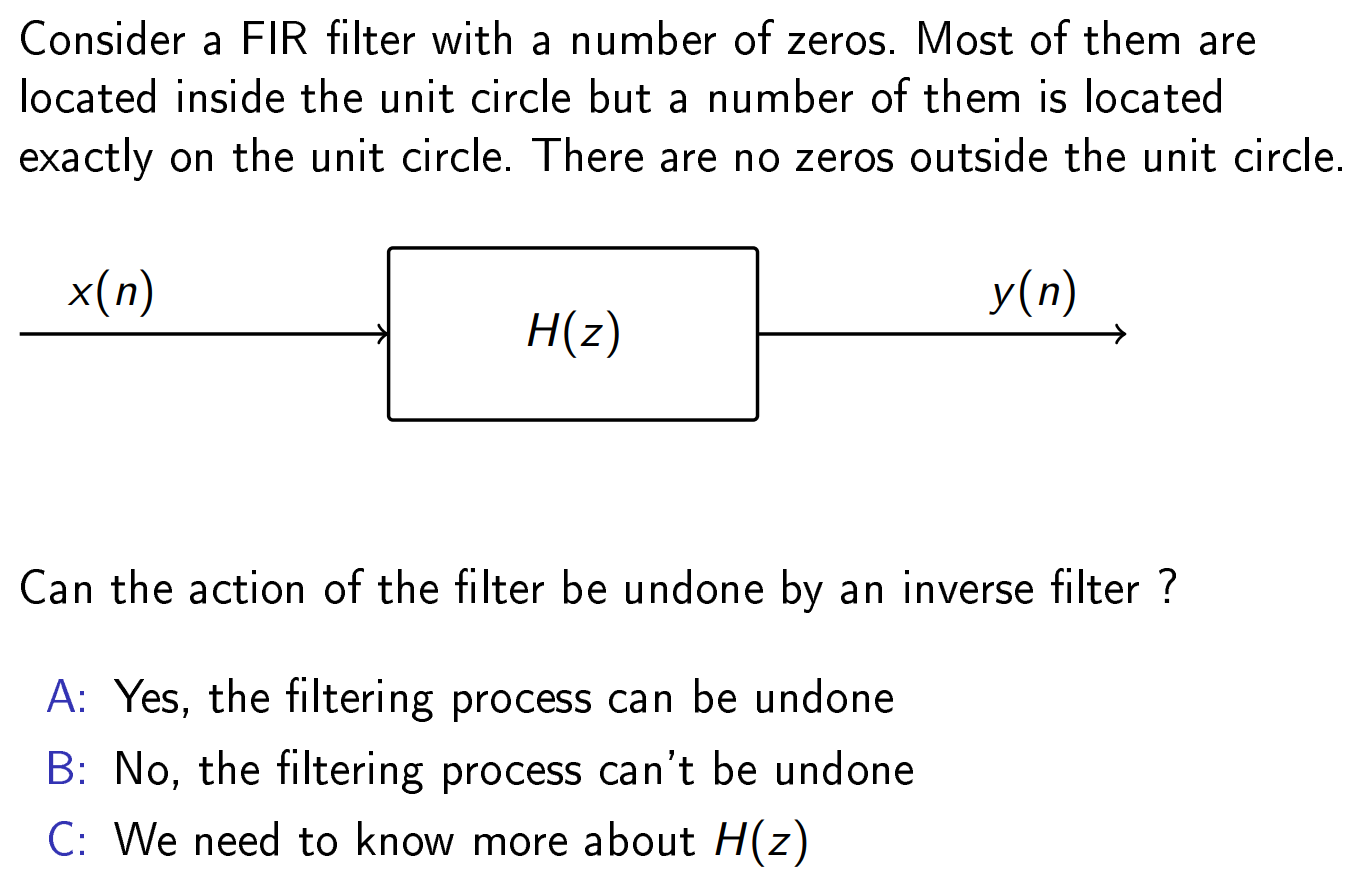

The answer is NO. If we have a FIR where the zero is exactly at 1 kHz. Given a signal, the filter will remove frequency component at 1 kHz. The problem is that the inverse filter cannot reconstruct the original signal because we have deleted information from the signal i.e., the missing frequency component cannot be recovered.

## Filter Decomposition

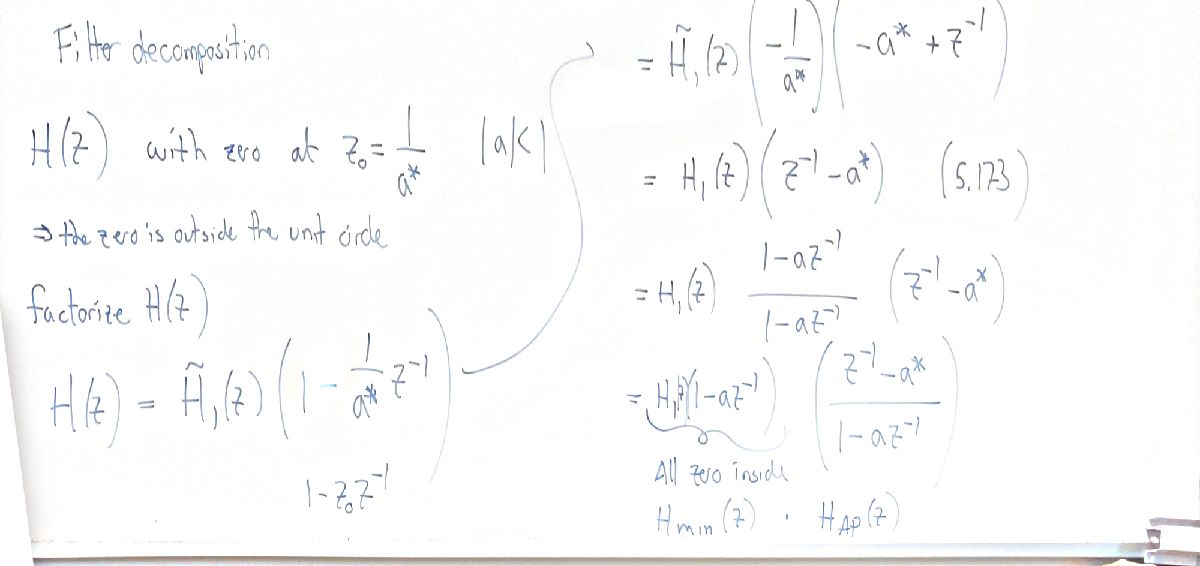

Notice that $H\left(z\right)$ has a zero outside the unit circle because $|a|<1$.

By decomposing $H\left(z\right)$ we made a new polynomial that consists of two parts:

- Minimum-phase system: all zeros are inside the unit circle

- All-pass system: which will have zeros outside the unit circle. We are basically storing all the phase in the all-pass filter instead

### Example:

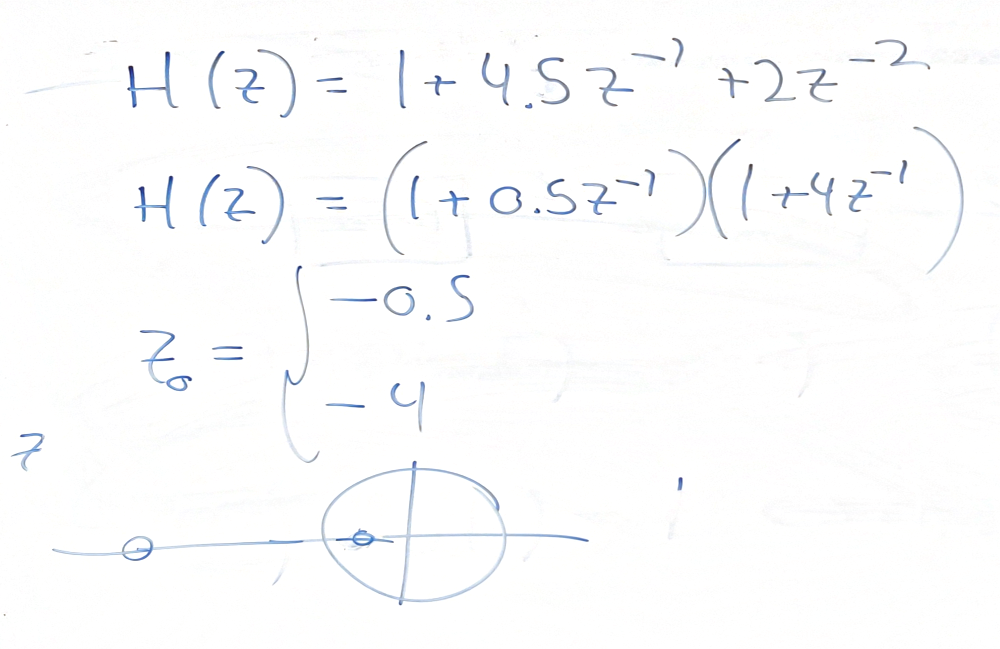

roots([1, 4.5, 2])

ans =    -4.0000
   -0.5000


One zero is inside the unit circle and the other is outside. We want to flip the zero outside the unit circle to be inside the unit circle.

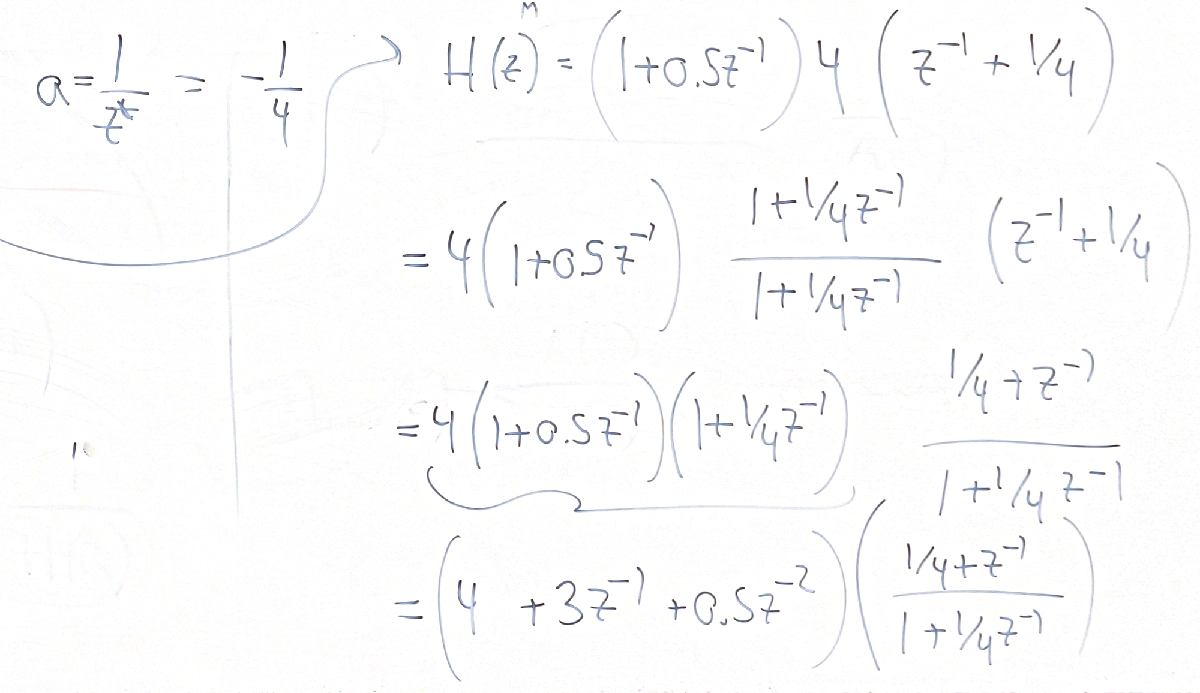

% Multiplying two polynomials together is the same
% as doing convolution.
4 * conv([1, 0.5], [1, 1/4])

ans =     4.0000    3.0000    0.5000


Plotting the maginatude response of the original system and the minimum-phase system, we observe that they are on top of each other

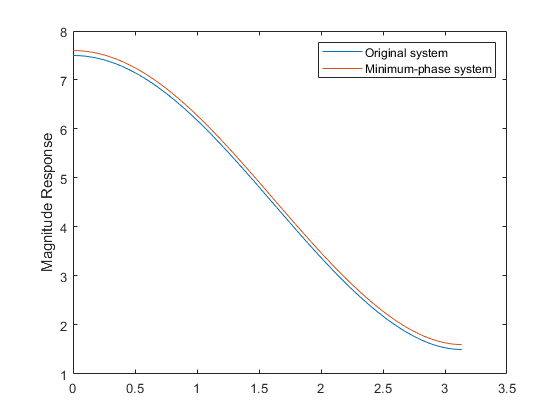

[H_orig, w] = freqz([1, 4.5, 2]); % Original
[H_min, w] = freqz([4, 3,   0.5]);
[H_ap, w] = freqz([1/4, 1], [1, 1/4]);

% Add 0.1 otherwise they will be on top of each other
plot(w, abs(H_orig), w, abs(H_min)+0.1)
legend('Original system', 'Minimum-phase system')
ylabel('Magnitude Response')

We can plot the phase of the three systems. The phase of the original system is hidden in the all-pass system. So by decomposing a filter into minimum-phase and all-pass systems, the excess phase is stored in the all-pass system.

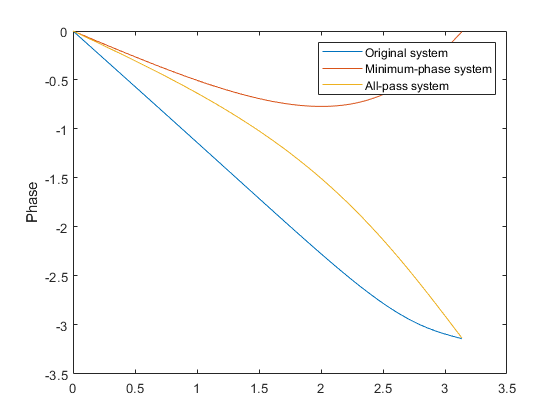

plot(w, angle(H_orig), w, angle(H_min), w, angle(H_ap))
ylabel('Phase')
legend('Original system', 'Minimum-phase system', 'All-pass system')

### Minimum Delay Property

What happens when we take a zero and flip it. We know that the magnitude response does not change.

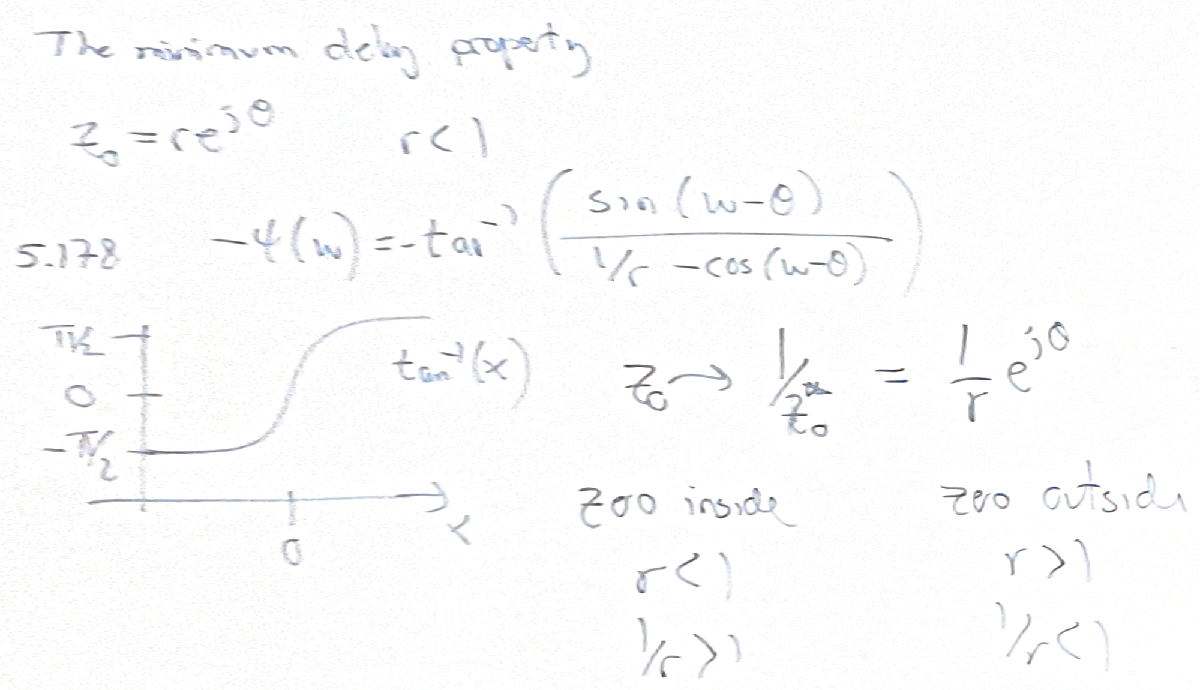

By setting $r<1$ we specifically place the zero inside the unit circle.

If we flip $z_0$ to $\frac{1}{z_0^* }=\frac{1}{r}e^{j\phi }$

If we have zero inside $r<1$ then $\frac{1}{r}>1$

If we have zero outside $r>1$ then $\frac{1}{r}<1$

The only thing that changes in the phase response when we flip $z_0$ to inside the unit circle is $\frac{1}{r}$.

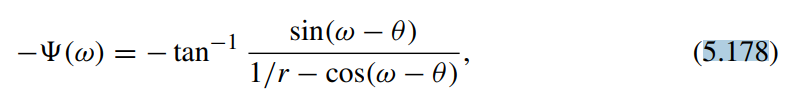

If we go from zero inside to outside, the $\frac{1}{r}$ becomes smaller. The tangent will increase and we get a larger number. This means that we get more phase. So we add phase as the zero goes from inside the unit circle to outside the unit circle. 

If we look at the group delay:

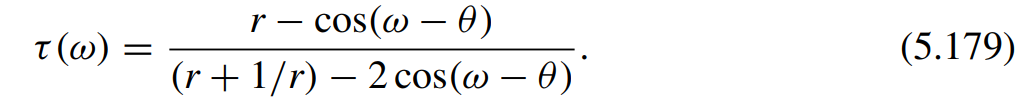

By taking a zero that is inside the unit circle and putting it outside, we increase the group delay.

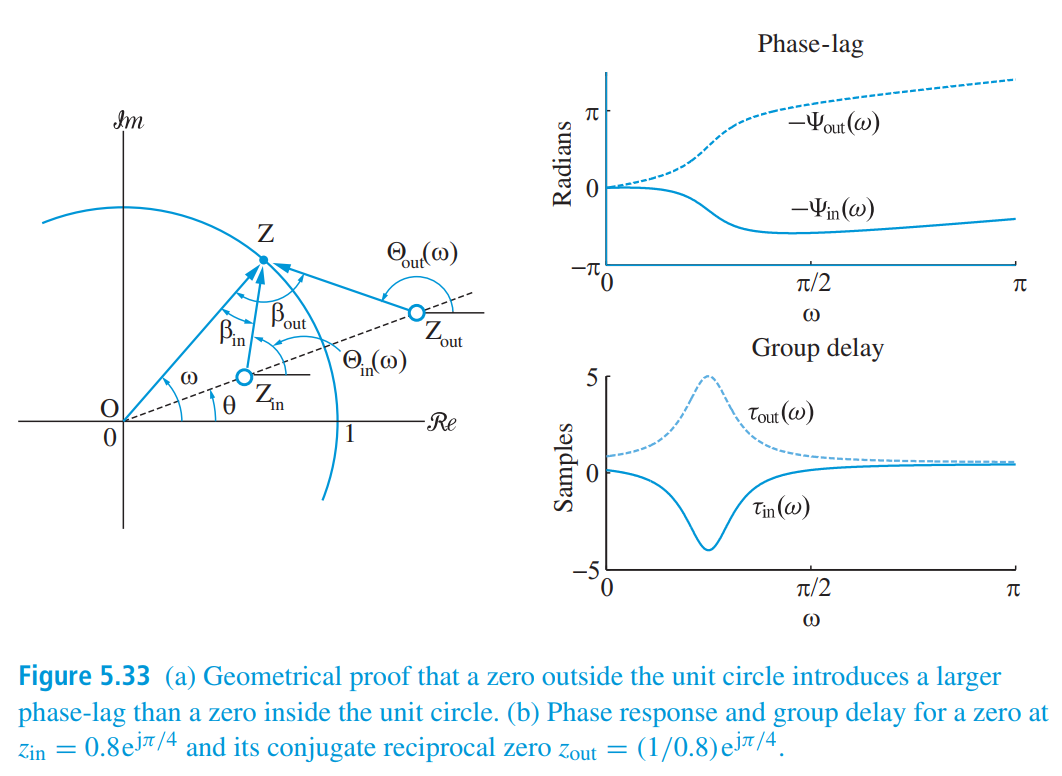

### Quiz

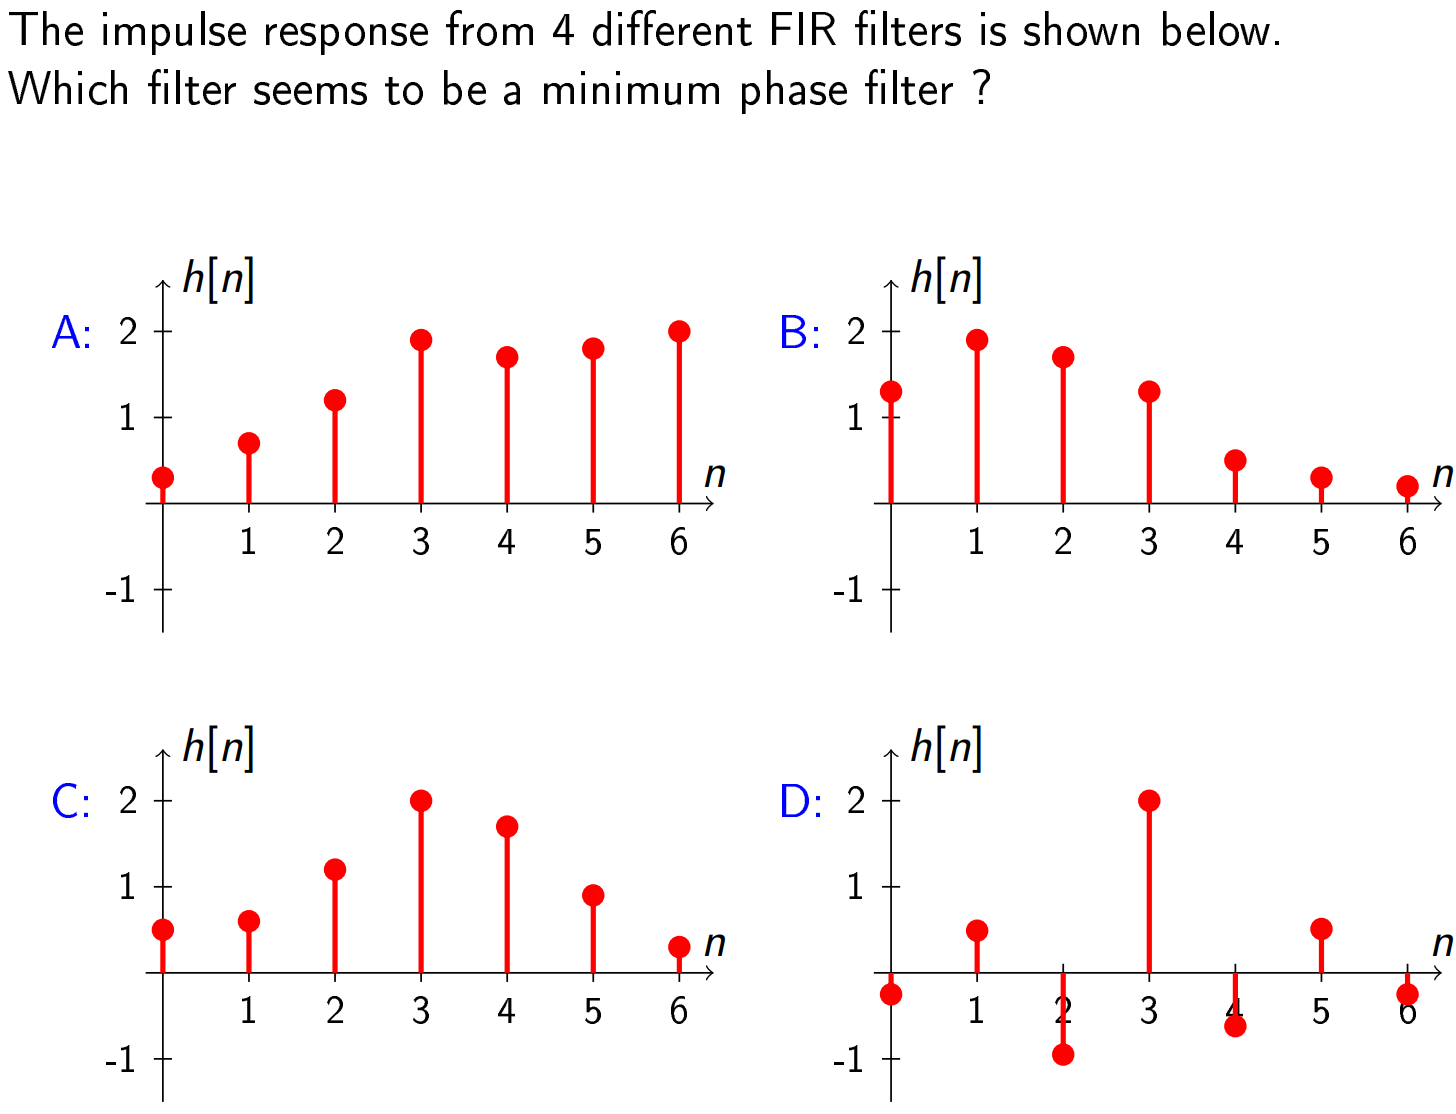

The answer is B. Minimum-phase is the same thing as minimum group delay. If we put in energy any of these four filters, which one is the fastest to respond and pass the signal though. How fast does the system propagate the energy of a signal through the filter? If it is slow, then it is maximum-phase. If a filter is in-between then it is mixed-phase. If it is very phase, then it is minimum-phase.

A and D has all the energy at the late end so it takes a while before all the energy passes through the system. Therefore, they has larger group delay than B, where the larger impulses are early. 

Comparing B and C: B has energy at the begining, whereas C the energy is in the middle. 

- A: Maximum-phase

- B: Minimum-phase

- C: Mixed-phase

- D: Mixed-hase

Let us simulate filter D in MATLAB:

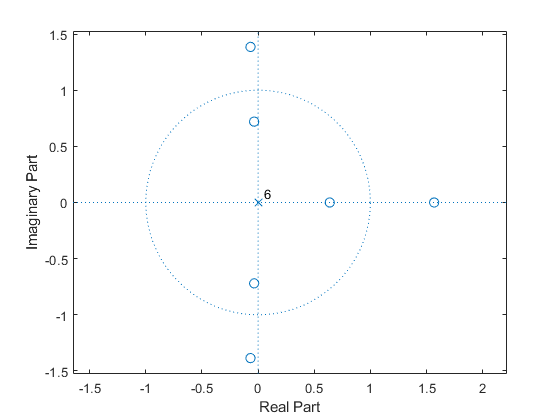

zplane([-1, 2, -3, 5, -3, 2, -1])

### Quiz

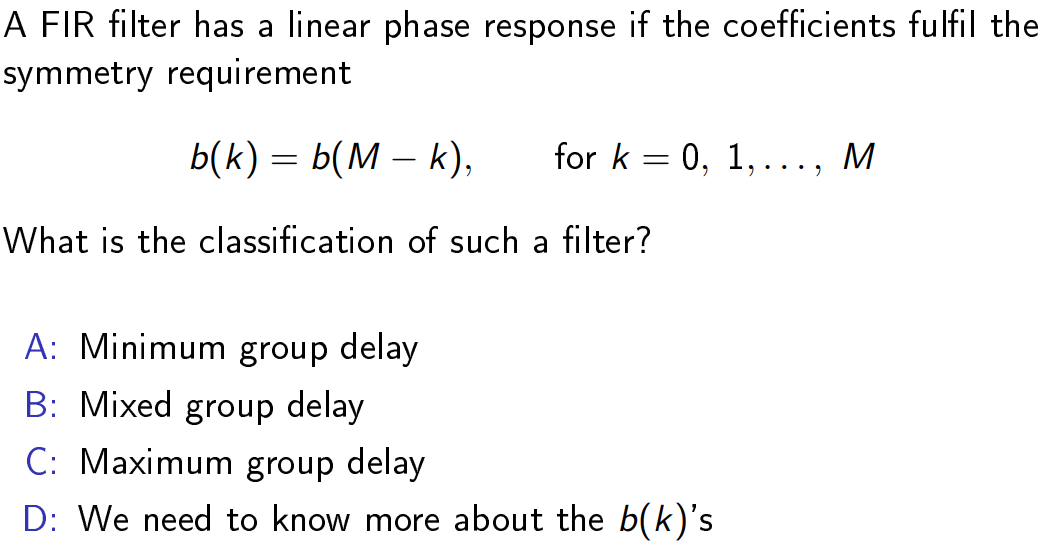

Recall that linear phase correspond to unity group delay. 

The symmetry will be in the middle of the filter. The answer is B.

We can try it out in MATLAB. If we plot the a linear phase filter, we get two zeros inside and two zeros outside. Thefore, the filter is mixed-phase filter.

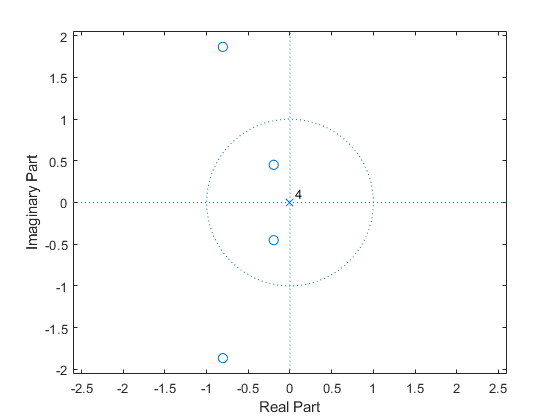

zplane([1, 2, 5, 2, 1])

The reason why the filter is called linear phase filter:

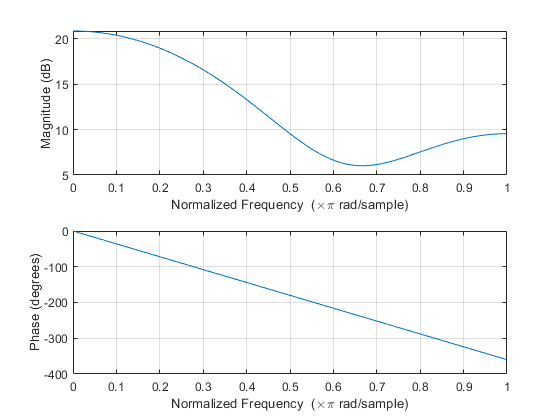

freqz([1, 2, 5, 2, 1])